#### Computational Experiment

To demonstrate that the no: zero eigen values of the (unnormalized) graph Laplacian is equal to the no: disconnected components or disconnected subgraphs (or the clusters)

**Toy examples**

These are toy examples.

Understand the concept using toy examples !

Demonstrate your understanding using toy examples !

**Example **$1$

$2$ zero eigen values $\Rightarrow$$2$ components

clearvars
rng(100)
N = 4;  %no: nodes

Make a random adjacency matrix(square symmetric)

A = rand(N);
A = A'*A;
Z =  zeros(size(A));

Build the Laplacian matrix of a graph with $2$ disconnected components.

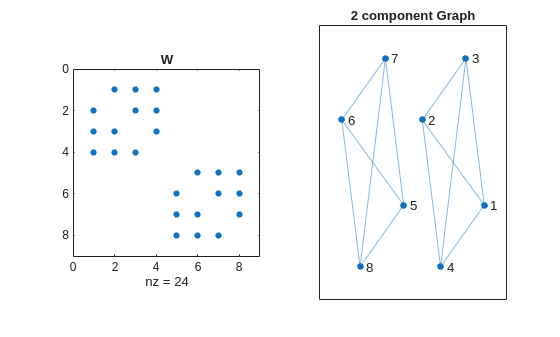

W = [A Z ;Z A];
W = W-diag(diag(W));

n = size(W,1);

D = diag(sum(W));

L_u = D - W;
L_n = eye(n) - pinv(D)*W;
L_ns = eye(n) - D^(-0.5)*W*D^(-0.5);

subplot(1,2,1)
spy(W)
title("W")

subplot(1,2,2)
plot(graph(W))
title("2 component Graph")


[eig(L_u) eig(L_n) eig(L_ns)]

ans =    -0.0000         0   -0.0000
   -0.0000    1.4338    1.4338
    2.7175    1.3618    1.3618
    2.7175    1.2043    1.2043
    3.7223         0   -0.0000
    3.7223    1.4338    1.4338
    3.8766    1.3618    1.3618
    3.8766    1.2043    1.2043


**Example **$2$

$3$ zero eigen values $\Rightarrow$$3$ components

clearvars
rng(100)
N = 4;  %no: nodes

Make a random adjacency matrix(square symmetric)

A = rand(N);
A = A'*A;
Z =  zeros(size(A));

Build the Laplacian matrix of a graph with $3$ disconnected components.

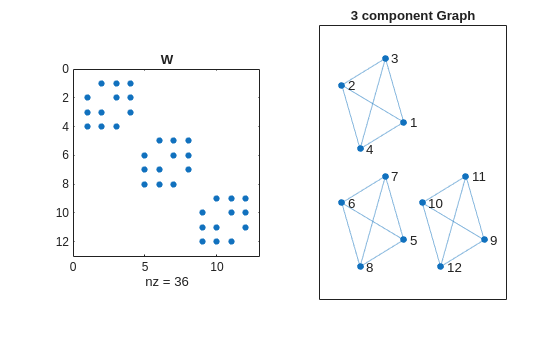

W = [A Z Z;Z A Z;Z Z A];
W = W-diag(diag(W));

n = size(W,1);

D = diag(sum(W));
L_u = D - W;
L_n = eye(n) - pinv(D)*W;
L_ns = eye(n) - D^(-0.5)*W*D^(-0.5);

subplot(1,2,1)
spy(W)
title("W")
subplot(1,2,2)
plot(graph(W))
title("3 component Graph")


[eig(L_u) eig(L_n) eig(L_ns)]

ans =    -0.0000         0   -0.0000
   -0.0000    1.4338    1.4338
   -0.0000    1.3618    1.3618
    2.7175    1.2043    1.2043
    2.7175         0   -0.0000
    2.7175    1.4338    1.4338
    3.7223    1.3618    1.3618
    3.7223    1.2043    1.2043
    3.7223         0   -0.0000
    3.8766    1.4338    1.4338
    3.8766    1.3618    1.3618
    3.8766    1.2043    1.2043


**Example **$3$** Using 'blkdiag' function**

$3$ zero eigen values $\Rightarrow$$3$ components

clearvars
rng(100)

Make a random adjacency matrix(square symmetric)

A = rand(4);
A = A'*A;

Build the Laplacian matrix of a graph with 3 disconnected components using blkdiag function.

W = blkdiag(A,A,A);
W = W-diag(diag(W));

n = size(W,1);

D = diag(sum(W));

L_u = D - W;
L_n = eye(n) - pinv(D)*W;
L_ns = eye(n) - D^(-0.5)*W*D^(-0.5);

subplot(1,2,1)
spy(W)
title("W")

subplot(1,2,2)
plot(graph(W))
title("3 component Graph")


[eig(L_u) eig(L_n) eig(L_ns)]

ans =    -0.0000         0   -0.0000
   -0.0000    1.4338    1.4338
   -0.0000    1.3618    1.3618
    2.7175    1.2043    1.2043
    2.7175         0   -0.0000
    2.7175    1.4338    1.4338
    3.7223    1.3618    1.3618
    3.7223    1.2043    1.2043
    3.7223         0   -0.0000
    3.8766    1.4338    1.4338
    3.8766    1.3618    1.3618
    3.8766    1.2043    1.2043


cd("/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/")
mlxfile = matlab.desktop.editor.getActive().Filename;
outfile = mlxfile + ".pdf";
export(matlab.desktop.editor.getActive().Filename, outfile,PageSize="A4");